# **PSP ASA Project - Colin Hezel**

## **Constants**

mu_v = 28303273; % Value of mu for Vulcan
AU = 149597898; % [km]
mu_sun = 132712449917.99; % [km3 / s2]
r_vulcan = 2.1 * AU; % Radius of vulcan in kilometers to the star
outer_orbit_radius = 500 + 50000; % [km]
inner_orbit_radius = 350 + 50000; % [km]

## Incoming Hyperbolic Orbit to Outer Orbit

e_hyp = 2; % Eccentricity of incoming orbit
periapsis_hyp = 1.8 * AU; % Periapsis of hyperbolic orbit in kilometers with reference to sun
p_hyp = periapsis_hyp * (1 + e_hyp); % Semi-latus rectum of the hyperbolic orbit
h_hyp = sqrt(p_hyp * mu_sun); % Angular momentum of the hyperbolic orbit
a_hyp = p_hyp / (1 - e_hyp^2); % Semi major axis of the hyperbolic orbit

v_hyp = sqrt(mu_sun * ( (2 / r_vulcan) - (1 / a_hyp) ) ); % Velocity of hyperbolic orbit
flight_angle_hyp = -1 * acosd(h_hyp / (r_vulcan * v_hyp)) % Flight path angle of the hyperbolic orbit

flight_angle_hyp = -25.6934


v_vulcan = sqrt(mu_sun / r_vulcan);
v_infinity = sqrt(v_hyp^2 + v_vulcan^2 - 2 * v_hyp * v_vulcan * cosd(flight_angle_hyp)); % Difference between vulcan velocity and hyperbolic velocity

e_vulcan_hyp = 1 + outer_orbit_radius * (v_infinity^2 / (mu_v) ); % Eccentricity of hyperbola once in Vulcan gravity
a_vulcan_hyp = -mu_v / v_infinity^2; % Semi major axis of hyperbola

outer_orbit_velocity = sqrt(mu_v * (1 / outer_orbit_radius)); % Velocity within the outer orbit
v_vulcan_hyp = sqrt(mu_v * ( (2 / outer_orbit_radius) - (1 / a_vulcan_hyp) ) ); 
delta_v_hyp = outer_orbit_velocity - v_vulcan_hyp

delta_v_hyp = -15.3934

## Outer Orbit to Transfer Orbit


apoapsis_trans = outer_orbit_radius; % Apoapsis of transitional orbit
periapsis_trans = inner_orbit_radius; % Periapsis of transitional orbit
a_trans = (apoapsis_trans + periapsis_trans) / 2; % Semi-major axis of transitional orbit
e_trans = (apoapsis_trans / a_trans) - 1; % Eccentricity of transitional orbit

a_v_trans = sqrt(mu_v * (2 / apoapsis_trans - 1 / a_trans)); % Velocity needed to begin transfer orbit
delta_v_1 = a_v_trans - outer_orbit_velocity % Change in velocity needed to enter into transfer orbit

delta_v_1 = -0.0176

## Transfer Orbit to Inner Orbit

inner_orbit_velocity = sqrt(mu_v * (1 / inner_orbit_radius));

p_v_trans = sqrt(mu_v * (2 / periapsis_trans - 1/ a_trans));
delta_v_2 = inner_orbit_velocity - p_v_trans % Change in velocity needed to enter inner orbit

delta_v_2 = -0.0176

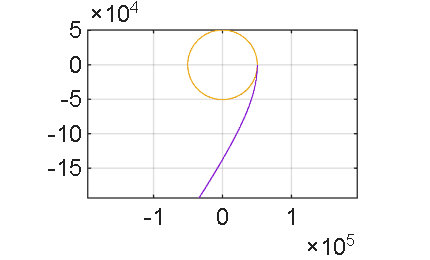

figure
orbitplot2D(a_trans, e_trans, 0:0.01:pi, 0, "Transfer");hold on
orbitplot2D(outer_orbit_radius, 0, 0:0.01: 2 * pi, 0, "Outer");
orbitplot2D(inner_orbit_radius, 0, 0:0.01: 2 * pi, 0, "Inner");
orbitplot2D(a_vulcan_hyp, e_vulcan_hyp, -deg2rad(100):0.01:0, 0, "Arrival Hyp")

grid on
axis equal